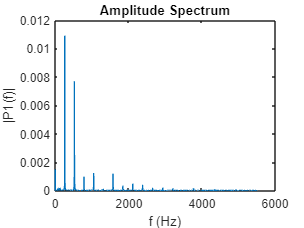

Fundamental Frequency for piano1.wav: 261.64 Hz


% Q1 
% Subproblem 1
fftPlot('piano1.wav')

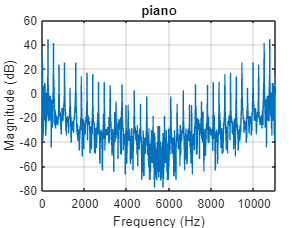

title('piano')

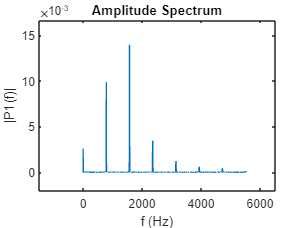

Fundamental Frequency for trumpet1.wav: 1566.24 Hz


% Q1 
% Subproblem 1
fftPlot('trumpet1.wav')

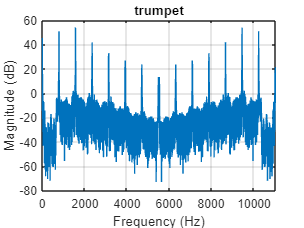

title('trumpet')

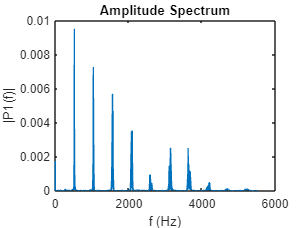

Fundamental Frequency for violin1.wav: 522.64 Hz


% Q1 
% Subproblem 1
fftPlot('violin1.wav')

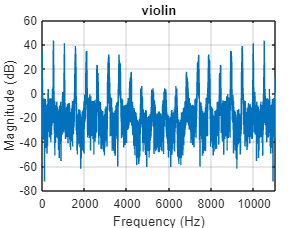

title('violin')

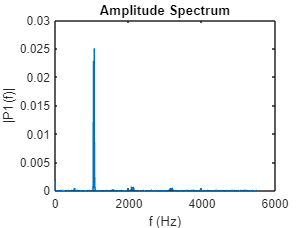

Fundamental Frequency for flute1.wav: 1063.20 Hz


% Q1 
% Subproblem 1
fftPlot('flute1.wav')

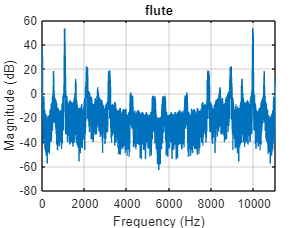

title('flute')

% Q1
% Subproblem 2
fundamentalFrequency('piano1.wav')

Fundamental Frequency for piano1.wav: 261.64 Hz


fundamentalFrequency('flute1.wav')

Fundamental Frequency for flute1.wav: 1063.20 Hz


fundamentalFrequency('piano2.wav')

Fundamental Frequency for piano2.wav: 523.62 Hz


fundamentalFrequency('flute2.wav')

Fundamental Frequency for flute2.wav: 524.33 Hz


fundamentalFrequency('piano3.wav')

Fundamental Frequency for piano3.wav: 1048.38 Hz


fundamentalFrequency('flute3.wav')

Fundamental Frequency for flute3.wav: 793.50 Hz


fundamentalFrequency('piano4.wav')

Fundamental Frequency for piano4.wav: 784.00 Hz


fundamentalFrequency('flute4.wav')

Fundamental Frequency for flute4.wav: 524.40 Hz


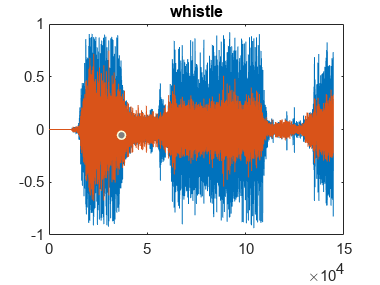

% Q2 part 2
[s1, Fs1] = audioread('whistle.wav');
plot(s1)
title('whistle')

fundamentalFrequency('whistle.wav')

Fundamental Frequency for whistle.wav: 1715.57 Hz
Fundamental Frequency for 1.715898e+03: 

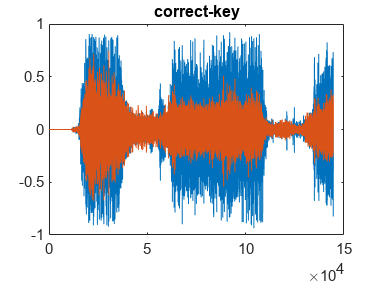

[s2, Fs2] = audioread('correct key.wav');
[s3, Fs3] = audioread('wrong key.wav');
plot(s2)
title('correct-key')

fundamentalFrequency('correct key.wav')

Fundamental Frequency for correct key.wav: 1715.57 Hz
Fundamental Frequency for 1.715898e+03: 

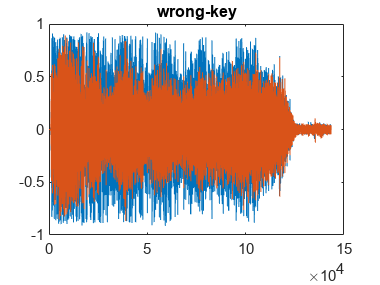

plot(s3)
title('wrong-key')

fundamentalFrequency('wrong key.wav')

Fundamental Frequency for wrong key.wav: 1693.21 Hz
Fundamental Frequency for 1.693208e+03: 

sound(s2, Fs3)



      
%Keylock('Whistling\key.wav')

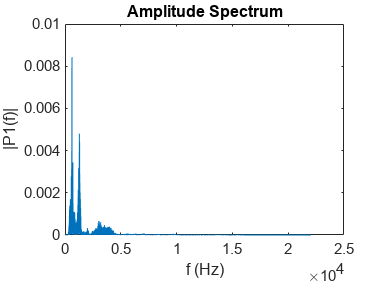

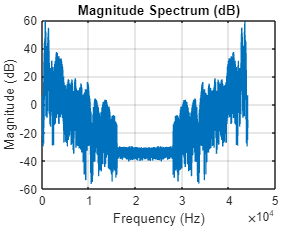

Fundamental Frequency for Opera.wav: 622.80 Hz


% Q3
fftPlot('Opera.wav')

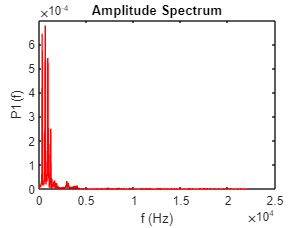

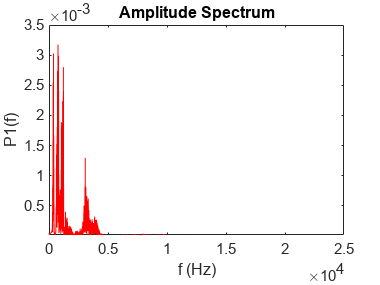

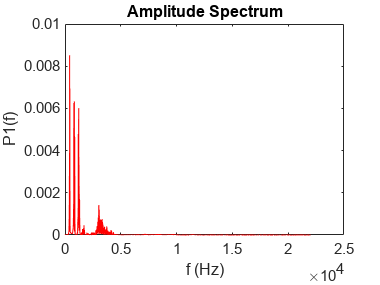

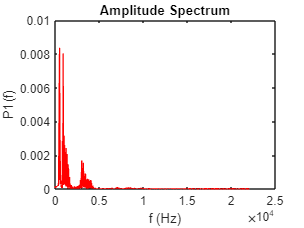

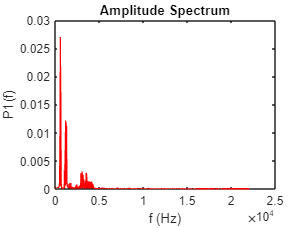

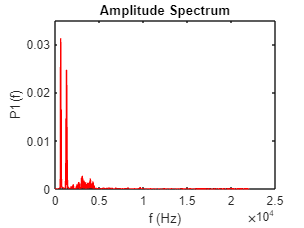

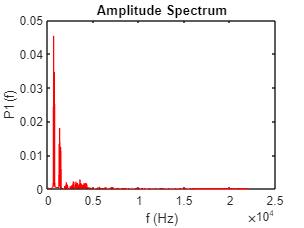

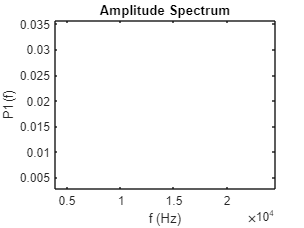

[s, Fs] = audioread('Opera.wav');
for i=1:11
    figure;
    audioSignal = (s(20000*(i-1)+1 :20000*i));
    % Compute the FFT of the audio signal
    fftResult = fft(audioSignal);
    L = length(audioSignal);
    
    % Plotting the Amplitude spectrum for each file
    f = Fs*(0:(L/2))/L;
    P2 = abs(fftResult/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    
    %[pks,locs] = findpeaks(P1);
    
    plot(f,P1,'r') 
    title('Amplitude Spectrum')
    xlabel('f (Hz)')
    ylabel('P1(f)')
end

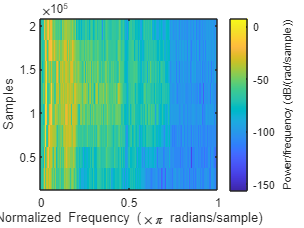


spectrogram(s)